# Análisis vertical    

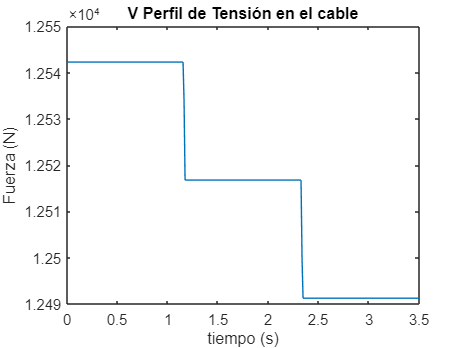

%Aceleración escogida vertical (Trapecoidal)
delta=0.01;
m=2;
t=0:delta:3.5;
vv=m*ctramp(t)-m*ctramp(t-3.5/3)-m*ctramp(t-2*3.5/3);
va=diff(vv);
t=linspace(0,3.5,length(va)); %Se redefine el tiempo para ajuste con la aceleración

%Estimaciones iniciales
masac=366.7;
densidadB=2.69/10/10/10;
masab=densidadB*130*130*20; %suposición de la bandeja
anchox=700/1000;
anchoy=700/1000;

%DCL caja
vN=masac*(va+9.81);

%(DCL bandeja)
vT=masab*(va+9.81)+vN; 
vMb=vN*1.22+(masab*9.81)*(1.22*3/4);

%DCL columna
vMx=vT.*(anchox/2-vMb);
vFz=vT;


%Impresión
plot(t,vT)
title('V Perfil de Tensión en el cable')
xlabel('tiempo (s)')
ylabel('Fuerza (N)')

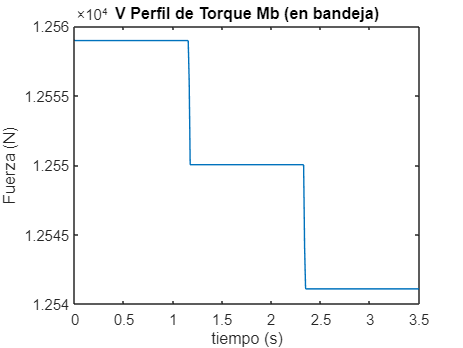


plot(t,vMb)
title('V Perfil de Torque Mb (en bandeja)')
xlabel('tiempo (s)')
ylabel('Fuerza (N)')

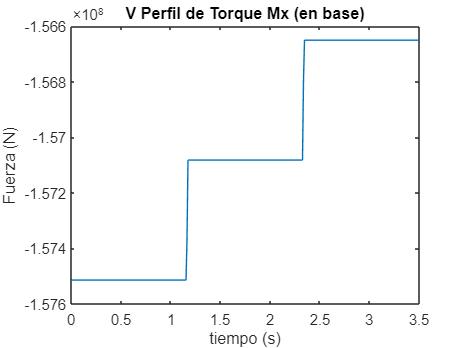


plot(t,vMx)
title('V Perfil de Torque Mx (en base)')
xlabel('tiempo (s)')
ylabel('Fuerza (N)')

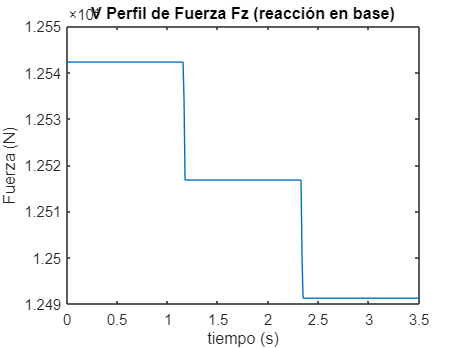


plot(t,vFz)
title('V Perfil de Fuerza Fz (reacción en base)')
xlabel('tiempo (s)')
ylabel('Fuerza (N)')

# Análisis horizontal

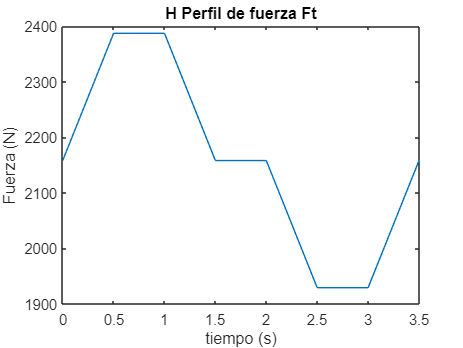

%Aceleración escogida horizontal (S-curve)
delta=0.01;
m=1.25;
t=0:delta:3.5;
%aceleración
ha=(m*ctramp(t)-m*ctramp(t-3.5/7)-m*ctramp(t-2*3.5/7)).*(t<3*3.5/7)...
    +(-1)*(m*ctramp(t-4*3.5/7)-m*ctramp(t-(5*3.5/7))-m*ctramp(t-(6*3.5/7))).*(t>4*3.5/7);
%velocidad
hv=zeros(size(ha));
r=0;
for i=1:length(hv)
    index=find(t<=r);
    hv(i) = delta*sum(ha(index));
    r=r+delta;
end
%desplazamiento
hs=zeros(size(ha));
r=0;
for i=1:length(hs)
    index=find(t<=r);
    hs(i) = delta.*sum(hv(index));
    r=r+delta;
end

t=linspace(0,3.5,length(ha)); %Se redefine el tiempo para ajuste con la aceleración

%Estimaciones iniciales
masac=366.7;
densidadB=2.69/10/10/10;
masab=densidadB*130*130*20; %suposición de la bandeja
anchox=700/1000;
anchoy=700/1000;
hUe=0.6; %Coeficiente fricción entre caja y bandeja (uñas)

%DCL caja 
hN=masac*9.81
hFt=masac*ha+hUe*hN; %Fuerza de transporte de caja

%DCL bandeja 
hT=hN+masab*9.81
hMe=hN*hs;
hMb=hN*(1.22)+(masab*9.81)*(1.22*3/4)
hMzban=(hFt-hUe*hN)*(1.22);

%DCL columna 
hMzbas=hMzban;
hMy=hMe;
hFz=hT
hMx=hT*(anchox/2)-hMb

%Impresión
plot(t,hFt)
title('H Perfil de fuerza Ft')
xlabel('tiempo (s)')
ylabel('Fuerza (N)')

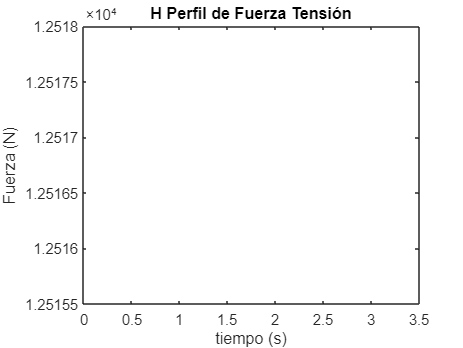


% plot(t,hT)
% title('H Perfil de Fuerza Tensión')
% xlabel('tiempo (s)')
% ylabel('Fuerza (N)')

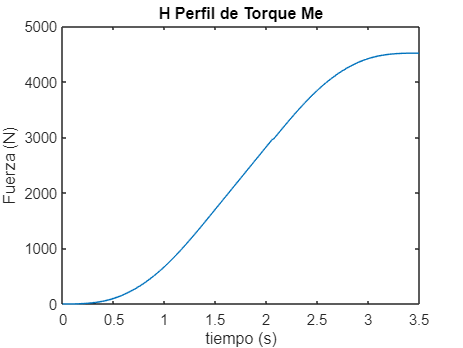


plot(t,hMe)
title('H Perfil de Torque Me')
xlabel('tiempo (s)')
ylabel('Fuerza (N)')

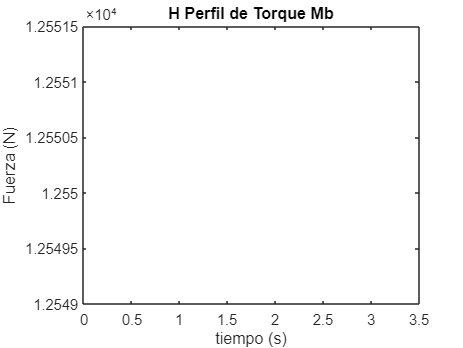


% plot(t,hMb)
% title('H Perfil de Torque Mb')
% xlabel('tiempo (s)')
% ylabel('Fuerza (N)')

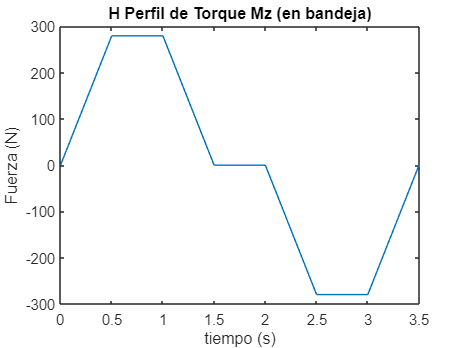


plot(t,hMzban)
title('H Perfil de Torque Mz (en bandeja)')
xlabel('tiempo (s)')
ylabel('Fuerza (N)')

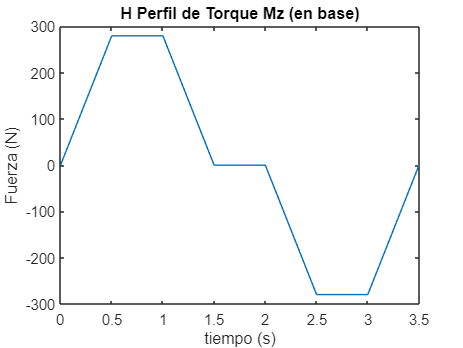


plot(t,hMzbas)
title('H Perfil de Torque Mz (en base)')
xlabel('tiempo (s)')
ylabel('Fuerza (N)')

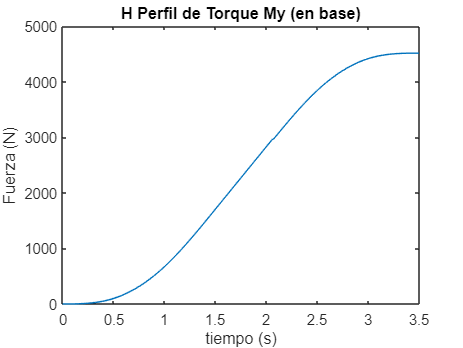


plot(t,hMy)
title('H Perfil de Torque My (en base)')
xlabel('tiempo (s)')
ylabel('Fuerza (N)')

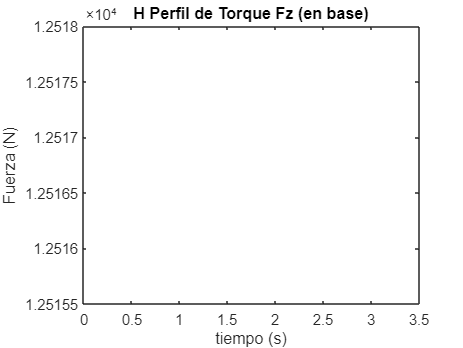


% plot(t,hFz)
% title('H Perfil de Torque Fz (en base)')
% xlabel('tiempo (s)')
% ylabel('Fuerza (N)')

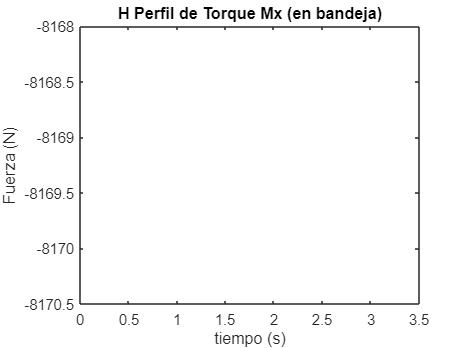


% plot(t,hMx)
% title('H Perfil de Torque Mx (en bandeja)')
% xlabel('tiempo (s)')
% ylabel('Fuerza (N)')